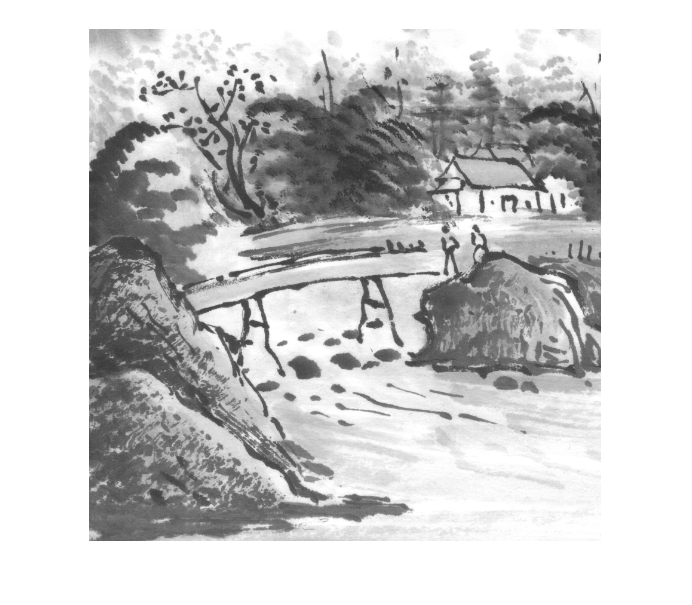

addpath('E:\BaiduSyncdisk\Matlab')
addpath('E:\BaiduSyncdisk\Matlab\VMIE')
addpath('E:\BaiduSyncdisk\Matlab\2DCS-ETC-master\TDCS-ETC\WaveletSoftware\')
addpath('E:\BaiduSyncdisk\Matlab\2DCS-ETC-master\TDCS-ETC\mywork')
P = imread("bridge512.bmp");
imshow(P)

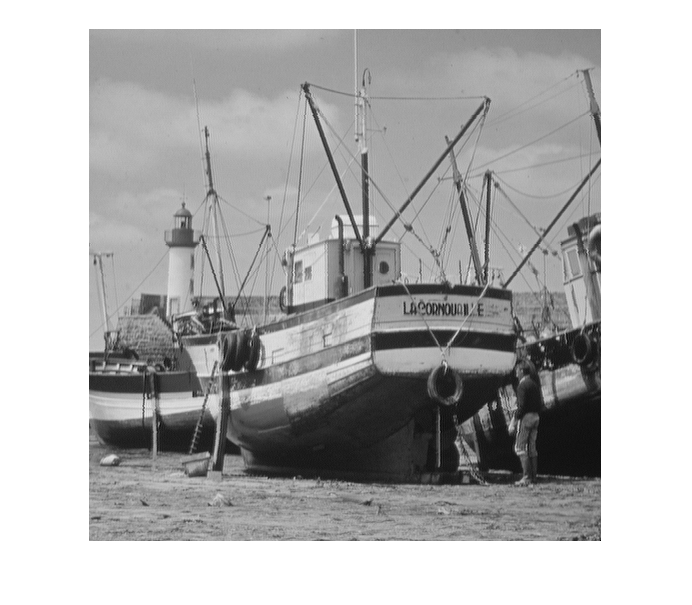

P = double(P);  % plain image
C = imread("Boat512.bmp");
imshow(C)

C = double(C);  % carriager image
[H, N] = size(P);
%Step1 Associated with the plain image(Last used)
Message = hash(P, 'SHA-256');  %输出为64位的十六进制数

m1 = hex2dec(Message(1:4))   + hex2dec(Message(5:8))   + hex2dec(Message(9:12))  + hex2dec(Message(13:16));
m2 = hex2dec(Message(17:20)) + hex2dec(Message(21:24)) + hex2dec(Message(25:28)) + hex2dec(Message(29:32));
m3 = hex2dec(Message(33:36)) + hex2dec(Message(37:40)) + hex2dec(Message(41:44)) + hex2dec(Message(45:48));
m4 = hex2dec(Message(49:52)) + hex2dec(Message(53:56)) + hex2dec(Message(57:60)) + hex2dec(Message(61:64));

c1 = RSA(m1, "encrypt");
c2 = RSA(m2, "encrypt");
c3 = RSA(m3, "encrypt");
c4 = RSA(m4, "encrypt");

%密钥流生成
x0=cos((floor(c1./m1)-c1./m1)*pi);
y0=cos((floor(c2./m2)-c2./m2)*pi);
z0=cos((floor(c3./m3)-c3./m3)*pi);
T = mod(floor(c1./m1)+floor(c2./m2)+floor(c3./m3)+floor(c4./m4),1000);
[X,Y,Z]=NewCheyLCM(x0,y0,z0,T,H*N);

% LSB嵌入
CR=0.5;
Phi1=PartHadamardMtx(H,N);
Phi2=PartHadamardMtx(H,N);
Rx1=X(1:H*CR);Rx2=X(1:N);
Ry1=X(1:H*CR);Ry2=X(1:N);
[~,Rx1Index]=sort(Rx1);
[~,Rx2Index]=sort(Rx2);
[~,Ry1Index]=sort(Ry1);
[~,Ry2Index]=sort(Ry2);
[~,Index]=sort(Z(:));
% X1=Quantization(X,256);
% Y1=Quantization(Y,256);
% Z1=Quantization(Z,256);
% chaoticList=zeros(8,ceil(H*N/8),3);
% chaoticList(:,:,1)=reshape(X1,8,ceil(H*N/8));
% chaoticList(:,:,2)=reshape(Y1,8,ceil(H*N/8));
% chaoticList(:,:,3)=reshape(Z1,8,ceil(H*N/8));
% rules=mod(Z1,6)+1;

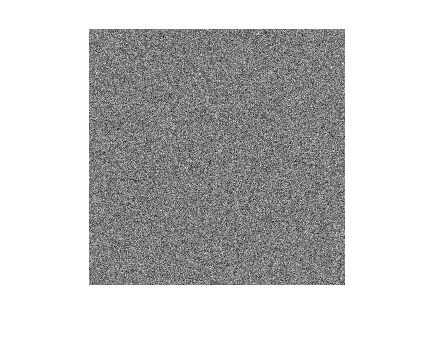

Phi1=Phi1(Rx1Index,Rx2Index);
Phi2=Phi2(Ry1Index,Ry2Index);
RBI=Quantization(Z,256);
RBI=reshape(S(RBI,H*N),H,N);
[Temp,Max,Min]=CS(P,Phi1,Phi2,Index,RBI);
imshow(uint8(Temp))

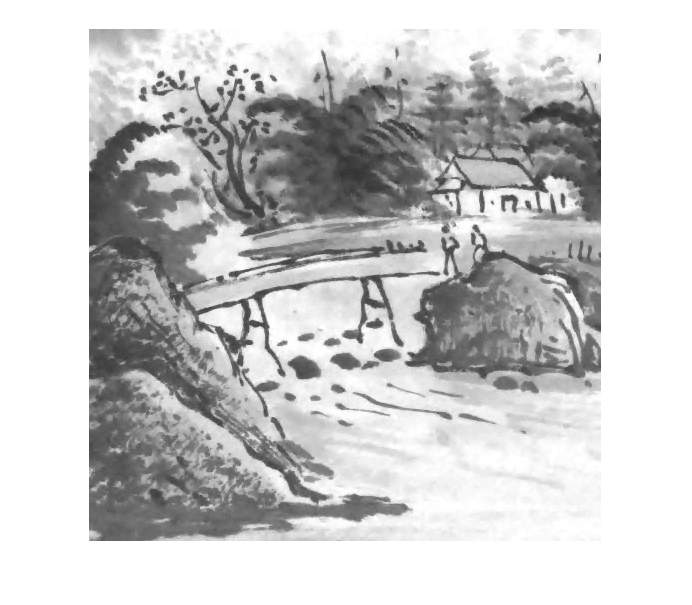

yq=IQuantization(Temp,Max,Min,256);

template_matrix=zeros(H,N)+128;

Y_template_matrix =  Phi1 *  template_matrix * Phi2';      %   Recover the 2DCS samples of the template matrix at the decoder side                       

Yq =yq + Y_template_matrix;                                             %   Recover the 2DCS samples

% Image reconstruciton by using 2D projected gradient with embedding decryption (2DPG-ED) algorithm.

reconstructed_image = TDPG_ED1 (Yq, Phi1, Phi2, ...
    RBI, Index, H, N, 3);

%reconstructed_image=Diffusion(double(uint8(reconstructed_image)),chaoticList,rules,"reverse");

imshow(uint8(reconstructed_image))


imshow(uint8(P))


psnr(uint8(reconstructed_image),uint8(P))

ans = 30.7952